First, clean up and set the environment

clear all
dq = daq("ni");
addoutput(dq, "Dev1", "ao0", "Voltage");
chi = addinput(dq, "Dev1", "ai0", "Voltage");
chi.Range = [-2, 2]
dq.Rate = 30000;
offset = 5;
amplitude_factor = 1;

Now let me get and process the intended to send signal

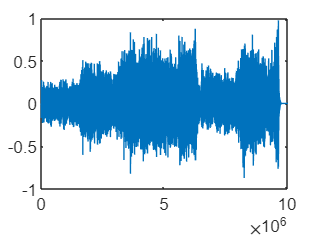

[audio, fs] = audioread("data/the-second-waltz-.mp3");
info = audioinfo("data/the-second-waltz-.mp3");
plot(audio(:, 1))

num_samples = info.TotalSamples + 2000;


try and transmit it:

data_gen = cat(1, cat(1, zeros(1000, 1), offset + audio(:, 1) * amplitude_factor), zeros(1000, 1));
preload(dq, data_gen);
start(dq);
data_dec = read(dq, seconds(230)); 
writetimetable(data_dec, 'second_waltz_reading_100_cm_volt_range_10.txt')
time2 = data_dec.Time(2:end);
temp = data_dec.Variables;
voltage2 = temp(2:end);
figure
plot(time2, voltage2)